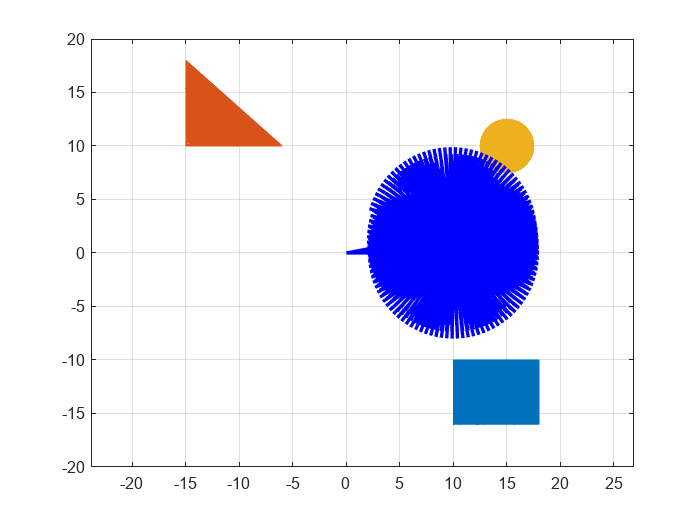


n = 10000;

%Rectangle Obstacle with random points inside;
x1 = [10,18,18,10,10]';           %set the corner of the Xpoints.
y1 = [-10,-10,-16,-16,-10]';      %set the corner of the Ypoints.



x11 = 10+8.*rand(n,1);           %set the random points of X
y11 = -(10+6.*rand(n,1));        %set the random points of Y

X1 = [x1;x11];          %colletive points in the space.
Y1 = [y1;y11];          %collective points in the space.


plot(X1,Y1)        

hold on

%Triangle with the obstacle points in it.
%same the above steps goes for the all other.
x2 = [-15 -6 -15,-15]';
y2 = [18,10,10,18]';

hold on 
x21 = -(6+9.*rand(n,1));
y21 = 10+8*rand(n,1);
p = y21 < 10 - (8/9)*(x21+6);

X2 = [x2;x21(p)];
Y2 = [y2;y21(p)];

plot(X2,Y2)

%Cirlce with random points of obstacle in it.

R3 = 2.5;


theta = linspace(0,2*pi,1000);
x3 = (15+R3*sin(theta))';
y3 = (10+R3*cos(theta))'; 
hold on

% Now create the set of points.
t = 2*pi*rand(n,1);
r = R3*sqrt(rand(n,1));
x31 = 15 + r.*cos(t);
y31 = 10 + r.*sin(t); 

X3= [x3;x31];
Y3= [y3;y31];
plot(X3,Y3)
axis([-20 20 -20 20])
axis equal
grid on;


X = [X1;X2;X3];
Y = [Y1;Y2;Y3];
cordObstacle = [X Y]

cordObstacle =    10.0000  -10.0000
   18.0000  -10.0000
   18.0000  -16.0000
   10.0000  -16.0000
   10.0000  -10.0000
   16.5178  -10.9229
   17.2463  -15.7708
   11.0159  -15.2575
   17.3070  -12.9318
   15.0589  -12.4425




l1 = 10;
l2 = 8;
theta1 = linspace(0,2*pi,100);
theta2 = linspace(0,2*pi,100);

for i=1:length(theta1)
    THETA1=theta1(i);
    for j = 1:length(theta2) 
        THETA2=theta2(j);
       
        x0 = 0;
        y0= 0;
        x1 = l1*cos(THETA1);
        y1= l1*sin(THETA1);
        x2 = x1+l2*cos(THETA2);
        y2 = y1+l2.*sin(THETA2);
      
        plot([x0 x1], [y0 y1], [x1 x2], [y1 y2], 'linewidth',2,'Color','blue')
        pause(1e-10000)
       
        grid on
    end
end
